# Interface Métodos Numéricos para ED/PVI

## 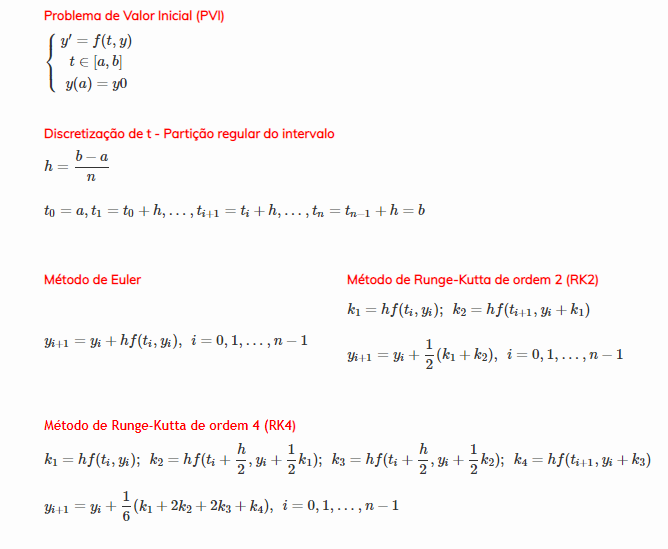

26/03/2021     Arménio Correia     armenioc@isec.pt

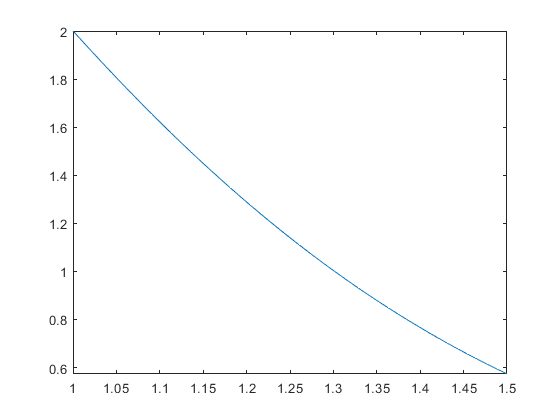

clear
syms y(t)

while 1
    %strF = input("f(t,y) = ","s");
    strF = "-2*t*y";
    f =@(t,y) eval(vectorize(strF));
    try
        fTeste = f(t,y);
        break
    catch ME
        waitfor(errordlg("Introduza uma função em t e y","Erro")) 
    end
end

while 1
    a = 1;
    if (isscalar(a) && isreal(a)) 
        break
    end
end

while 1
    b = 1.5;
    if (isscalar(b) && isreal(b) && b>a) 
        break
    end
end
n = 20;
y0 = 2;

yEuler = NEuler(f,a,b,n,y0);
yRK2 = NRK2(f,a,b,n,y0);

sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0);
fplot(sExata,[a,b]);


g =@(t) eval(vectorize(char(sExata)));

h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroEuler = abs(yExata-yEuler);
erroRK2 = abs(yExata-yRK2);
tabela = [t.',yExata.',yEuler.',yRK2.',erroEuler.',erroRK2.']

tabela =     1.0000    2.0000    2.0000    2.0000    0.0000    0.0000
    1.0250    1.9013    1.9000    1.9013    0.0013    0.0000
    1.0500    1.8052    1.8026    1.8052    0.0025    0.0001
    1.0750    1.7118    1.7080    1.7119    0.0038    0.0001
    1.1000    1.6212    1.6162    1.6213    0.0050    0.0002
    1.1250    1.5335    1.5273    1.5337    0.0062    0.0002
    1.1500    1.4487    1.4414    1.4489    0.0073    0.0002
    1.1750    1.3669    1.3585    1.3671    0.0084    0.0003
    1.2000    1.2881    1.2787    1.2884    0.0094    0.0003
    1.2250    1.2123    1.2020    1.2126    0.0103    0.0003


array2table(tabela,"VariableNames",{'t','Exata','Euler','RK2','erroEuler','erroRK2'})

ans = 21×6 table
      t       Exata      Euler       RK2      erroEuler      erroRK2  
    _____    _______    _______    _______    __________    __________

        1          2          2          2    4.4409e-16    4.4409e-16
    1.025     1.9013        1.9     1.9013     0.0012702    4.2316e-05
     1.05     1.8052     1.8026     1.8052     0.0025313    8.3474e-05
    1.075     1.7118      1.708     1.7119      0.003773    0.00012332
      1.1     1.6212     1.6162     1.6213     0.0049856    0.00016171
    1.125     1.5335     1.5273     1.5337     0.0061604    0.00019851
     1.15     1.4487     1.4414     1.4489     0.0072893     0.0002336
    1.175     1.3669     1.3585     1.3671     0.0083652    0.00026687
      1.2     1.2881     1.2787     1.2884     0.0093818    0.000298

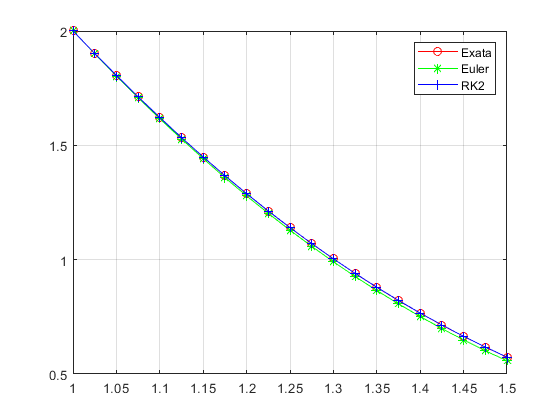


plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
plot(t,yRK2,"-b+")
hold off
grid on
legend('Exata','Euler','RK2')